# Adding biological constraints to a flux balance model

## Authors: Diana C. El Assal and Ronan M.T. Fleming,  Luxembourg Centre for Systems Biomedicine, University of Luxembourg, Luxembourg.

## Reviewers: Anne Richelle, Systems Biology and Cell engineering, University of California San Diego

## INTRODUCTION

A metabolic model can be converted into a condition-specific model based on the imposition of experimentally derived constraints. Constraints can be defined for each reaction, such as upper and lower flux bounds for each reaction, equality and/or inequality constraints. These represent specific intra- and extracellular conditions (e.g. environmental constraints, maximum enzyme capacity, biomass maintenance requirements)[1].  

## PROCEDURE

Load the model into the workspace. For this tutorial, we have choosen to use Recon2.0 model for illustration, although any model can be used. 

clear model
if ~exist('modelOrig','var')
    load('Recon2.0model.mat');
    model = Recon2model;
    model.csense(1:size(model.S,1),1)='E';
else
    model=modelOrig;
    model.csense(1:size(model.S,1),1)='E';
end

## **1. Environmental constraints**

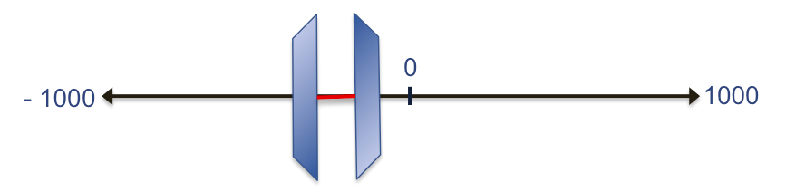

The environmental constraints are typically related to the nutrient availability (e.g., glucose and oxygen). They can be defined using the function *changeRxnBounds* to set the minimal and maximal uptake and/or secretion rates possible in a specific condition. For example, in the caudate-putamen of the conscious rat, the glucose consumption rate was found to range between -12.00 and -11.58  $\mu mol/gDW/hr$[4]. Therefore, the lower bound of the glucose exchange reaction (*EX_glc(e)*) can be set as follows:

modelConstrained = changeRxnBounds(model, 'EX_glc(e)', -12, 'l');

To further constrain the model, an upper bound can also be imposed to force the model to take up between 11.58 and 12 units of glucose 

modelConstrained = changeRxnBounds(modelConstrained, 'EX_glc(e)', -11.58, 'u');

## **2. Internal enzymatic constraints **

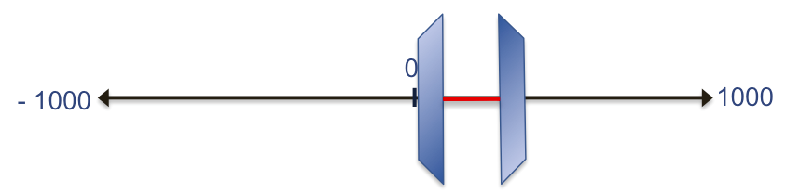

By convention, the bounds set on reaction rates in a metabolic model range from -1000 to 1000 for reversible reactions and from 0 to 1000 for irreversible ones [1]. Actually, the rate of a reaction is related to the activity of the enzyme catalyzing this reaction. Therefore, internal enzymatic constraints can be used to define the maximum capacity of a specified enzyme to catalyze a reaction (*Vmax*). For example, assuming that the reaction catalyzed by fructose-bisphosphate aldolase ([FBA](http://vmh.uni.lu/#reaction/FBA)) has a *Vmax *of 128 units, one can set an upper bound on the corresponding internal reaction FBA:

modelConstrained = changeRxnBounds(modelConstrained, 'FBA', 128, 'u');

Optionally, if the reaction is reversible, the same constraint can be set as the lower bound, but with an opposite sign:

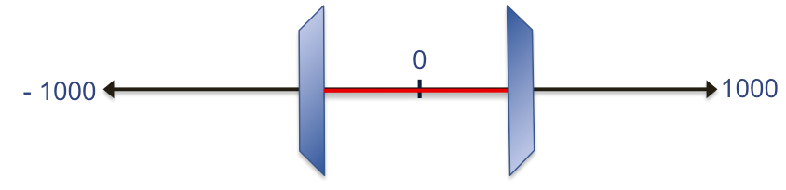

modelConstrained = changeRxnBounds(modelConstrained, 'FBA', -128, 'l');

## **3. Constraints associated with biomass**

**3.1. Biomass reaction**

In general, biomass constraints [2] are added as part of a biomass reaction by defining stoichiometric coefficients for each biomass precursor. For dividing cell types, the generic human biomass reaction available in Recon2 is formulated as follows:

printRxnFormula(modelConstrained, 'biomass_reaction');

biomass_reaction	20.6508 h2o[c] + 20.7045 atp[c] + 0.385872 glu_L[c] + 0.352607 asp_L[c] + 0.036117 gtp[c] + 0.279425 asn_L[c] + 0.505626 ala_L[c] + 0.046571 cys_L[c] + 0.325996 gln_L[c] + 0.538891 gly[c] + 0.392525 ser_L[c] + 0.31269 thr_L[c] + 0.592114 lys_L[c] + 0.35926 arg_L[c] + 0.153018 met_L[c] + 0.023315 pail_hs[c] + 0.039036 ctp[c] + 0.154463 pchol_hs[c] + 0.055374 pe_hs[c] + 0.020401 chsterol[c] + 0.002914 pglyc_hs[c] + 0.011658 clpn_hs[c] + 0.053446 utp[c] + 0.009898 dgtp[n] + 0.009442 dctp[n] + 0.013183 datp[n] + 0.013091 dttp[n] + 0.275194 g6p[c] + 0.126406 his_L[c] + 0.159671 tyr_L[c] + 0.286078 ile_L[c] + 0.545544 leu_L[c] + 0.013306 trp_L[c] + 0.259466 phe_L[c] + 0.412484 pro_L[c] + 0.005829 ps_hs[c] + 0.017486 sphmyln_hs[c] + 0.352607 val_L[c] 	->	20.6508 adp[c] + 20.6508 h[c] + 20.6508 pi[c] 


Any changes or adaptations can be introduced by adding a new formulation of the biomass function, using the function *addReaction*. For example, one can add the following new biomass reaction named *biomassReactionLipids*:

modelConstrained = addReaction(modelConstrained, 'biomasReactionLipids',  '20.6508 h2o[c] + 20.7045 atp[c] + 0.15446 pchol_hs[c] + 0.055374 pe_hs[c] + 0.020401 chsterol[c] + 0.011658 clpn_hs[c] + 0.005829 ps_hs[c] + 0.017486 sphmyln_hs[c] -> 20.6508 h[c] + 20.6508 adp[c] + 20.6508 pi[c]');

test
biomasReactionLipids	20.6508 h2o[c] + 20.7045 atp[c] + 0.15446 pchol_hs[c] + 0.055374 pe_hs[c] + 0.020401 chsterol[c] + 0.011658 clpn_hs[c] + 0.005829 ps_hs[c] + 0.017486 sphmyln_hs[c] 	->	20.6508 adp[c] + 20.6508 h[c] + 20.6508 pi[c] 


## **3.1. Biomass maintenance reaction**

Knowledge related to the minimal requirements for biomass maintenance can also be used constraint reactions related to biomass. Indeed, some cell types (e.g. neurons) does not divide, but only require to turn over their biomass components. Using literature references, the degradation pathways for each biomass precursor can be identified and the first reactions of these degradation pathways can be mapped to Recon2 model and constrained. For example, Table 1 presents the minimal biomass maintenance requirements of neurons in the human grey matter. These reaction rates can be imposed as a lower bound on the corresponding degradation reactions of the different lipids, amino acids, and nucleic acids presented in the table. 

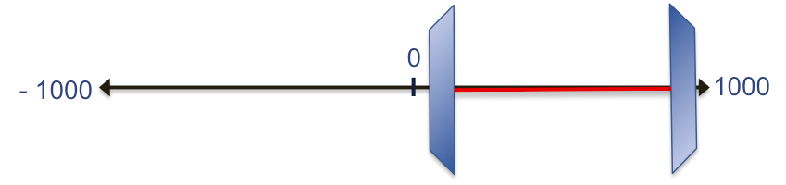

**Table 1: The minimum metabolic maintenance requirement for neurons.** This is a coarse-grained approximation of neuronal lipid, amino acid, and nucleic acid maintenance requirements converted into $\mu mol/gDW/hr$.

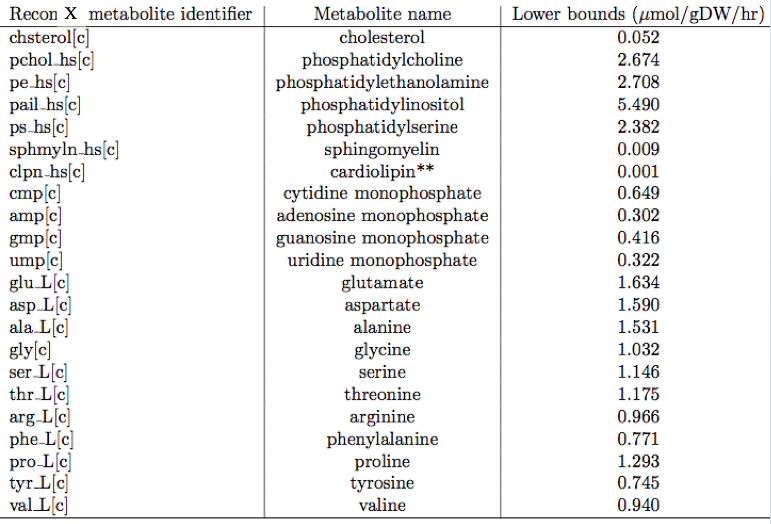

 **cardiolipin is also known as diphosphatidylglycerol 

When these values are not available in literature, one can calculated these reactions rates ($\mu mol/gDW/hr$) using the fractional composition (i.e., molar abundance) and the turnover rate of each biomass precursor. Turnover rates are commonly expressed as half-lives (${t_{1/2}$) and represent the time required for half of the biomass precursor to be replaced [3]. 

Using the experimental literature, metabolite half-lives (${t_{1/2}$) can be collected and converted into turnover rates ($\lambda$):


$$\text{(1)}\ \lambda=\frac{ln(2)}{t_{1/2}}\\
$$


***Calculation example of the minimal cholesterol maintenance requirement ***

***i. Identify metabolite abundance***

Assuming that the specific tissue type has a total dry weight lipid composition of 39.6%. This means that there is 0.396g Lipid per gDW of tissue. If cholesterol has a molar composition of 31.3%, then in total there is 0.124g cholesterol per gDW of tissue.

abundance = (31.3*39.6*1)/(100*100)

abundance = 0.1239

***ii. Calculate the molar abundance***

In the experimental literature, cholesterol was found to have a molar mass ($M$) of 386 g/mol. Using equation (2), we can now convert the abundance (*m*) into molar units (*n*). 


$$
\text{(2)}\ n=\frac{m}{M}
$$


M = 386; %g/mol
n = (abundance*1000000)/M %micromol

n = 321.1088

***ii. Calculate the corresponding flux value***

In the brain, cholesterol has a very slow turnover and a ${t_{1/2}$ of 4320 hours. Using equation (1), we can now calculate the minimal cholesterol maintenance requirement in flux units ($v_1$). 

halfLife = 4320;
turnover = log(2)/halfLife;
v1 = n * turnover

v1 = 0.0515

The minimal cholesterol maintenance requirement was calculated to be 0.0515$\mu mol/gDW/hr$(Table 1). This value can be used as a lower bound in the corresponding reaction.

## **3.2. **Identification of degradation reactions for a biomass maintenance precursor

As said before, the degradation pathways for each biomass precursor can be identified using literature and the minimal maintenance requirements defined in section 3.1. can be used to constraint the first reactions of these degradation pathways. However, the identification of these reactions and the set-up of associated constraints is not always straightforward. The following section presents the different common cases that can be encountered.

## A. Single degradation reaction does not exist biochemically

A degradation reaction might not exist for a given biomass maintenance precursor. For example, the phospholipid cardiolipin is mainly present in the inner mitochondrial membrane, where it regulates the stability of the mitochondrial membrane protein complexes [4]. As part of mitochondria, cardiolipin reaches the lysosome during macroautophagy [5] and is then degraded to form the negatively charged bis(monoacylglycero)phosphate (BMP) on internal membranes.  

If the corresponding demand reaction does not exist in the model, a demand reaction can be added using the function *addDemandReaction*. 

modelConstrained = addDemandReaction(modelConstrained, 'clpn_hs[c]');

DM_clpn_hs[c]	clpn_hs[c] 	->	


The constraint associated with cardiolipin requirement (Table 1) can be imposed on this new demand reaction called *DM_clpn_hs[c]*

modelConstrained = changeRxnBounds(modelConstrained, 'DM_clpn_hs[c]', 0.001, 'l');

## B. Single irreversible degradation reaction

In cases where only a single irreversible degradation reaction exists for a biomass maintenance precursor, the imposition of the constraint is straightforward. For example, the major cholesterol excretion pathway in the brain involves the hydroxylation of cholesterol into the oxysterol 24-hydroxycholesterol. Only a subset of neurons express this 24-hydroxylase enzyme ([HMR_1735](http://vmh.uni.lu/#human/all/HMR_1735)) and it is mainly found in dendrites and somata, rather than in axons or presynaptic terminals [6]. 

Therefore, the minimal maintenance requirement for cholesterol calculated in the previous section ($v_1$) can be imposed as a lower bound on HMR_1735 (Table 1). 

modelConstrained = changeRxnBounds(modelConstrained, 'HMR_1735', v1, 'l');

## C. Single reversible degradation reaction

In cases where the biomass precursor degradation reaction is reversible, the reaction first needs to be split into two irreversible reactions. To this end, define the set of reversible degradation reactions (sRxns) and convert them into two irreversible reactions (i.e., *sRXN_b* and *sRXN_f*, respectively backward and forward reactions) using *convertToIrreversible:*

sRxns = {'ASPTA'; 'GHMT2r'};% reaction associated with the aspartate and glutamate degradation
[modelIrrev] = convertToIrreversible(modelConstrained,'sRxns',sRxns);

You can check if the conversion as been done properly by searching the splitted reaction

for j=1:length(sRxns)
    if isempty(findRxnIDs(modelIrrev, [sRxns{j} '_f']))
        error('Forward reaction not found')
    end
    if isempty(findRxnIDs(modelIrrev, [sRxns{j} '_b']))
        error('Reverse reaction not found')
    end
end

You can also identify the new reaction names as follows:

rxnsIrrev = setdiff(modelIrrev.rxns, modelConstrained.rxns)


rxnsIrrev =

  0×1 empty cell array



Manually identify the corresponding reactions that should be constrained in *rxnsIrrev *(e.g., the respective forward reactions) and their associated indices using *findRxnIDs *and set the constraints that have been previously defined for these two biomass precursors (Table1).  Note that you can easily account for experimental errors by defining a percentage error (e.g., *expError = 0.25*) for the constraint values 

splitRxns= {'ASPTA_f'; 'GHMT2r_f'};
constraints = [1.590; 1.146];
expError = 0.25;
modelConstrained = changeRxnBounds(modelIrrev, splitRxns,constraints-constraints.*expError, 'l')

modelConstrained = struct with fields:
                      S: [5063×7444 double]
                   rxns: {7444×1 cell}
                     lb: [7444×1 double]
                     ub: [7444×1 double]
                    rev: [7440×1 double]
                      c: [7444×1 double]
             rxnGeneMat: [7444×2194 double]
                  rules: {7444×1 cell}
                  genes: {2194×1 cell}
                grRules: {7444×1 cell}
             subSystems: {7444×1 cell}
               rxnNames: {7444×1 cell}
              rxnKeggID: {7440×1 cell}
    rxnConfidenceEcoIDA: {7440×1 cell}
    rxnConfidenceScores: {7440×1 cell}
             rxnsboTerm: {7440×1 cell}
          rxnReferences: {7440×1 cell}
           rxnECNumbers: {7440×1 cell}
               rxnNotes: {7440×1 cell}
                   mets: {5063×1 cell}
                      b: [5063×1 double]
               metNames: {5063×1 cell}
            metFormulas: {5063×1 cell}
              metCharge: [5063×1 double]
   

## D. Multiple irreversible degradation reactions

In some cases, several degradation pathways may be available for one biomass precursor. For example, phosphatidylcholine (PC) can be degraded by 3 different metabolic pathways in the brain [7]:

- [PCHOLP_hs](http://vmh.uni.lu/#reaction/PCHOLP_hs): Phospholipase D acts on the choline/phosphate bond of PC to form choline and phosphatidic acid.

- [PLA2_2](http://vmh.uni.lu/#reaction/PLA2_2): Phospholipase A2 acts on the bond between the fatty acid and the hydroxyl group of PC to form a fatty acid (e.g. arachidonic acid or docosahexaenoic acid) and lysophosphatidylcholine. 

- [SMS](http://vmh.uni.lu/#reaction/SMS): Ceramide and PC can also be converted to sphingomyelin by sphingomyelin synthetase. 

Define the set of potential reactions associated with the degradation of PC

multipleRxnList={'PCHOLP_hs', 'PLA2_2', 'SMS'};

Check that they are irreversible (i.e. the lower bounds should be 0 and the upper bounds should be a positive value).  

modelConstrained.lb(findRxnIDs(model, multipleRxnList))

ans =      0
     0
     0


modelConstrained.ub(findRxnIDs(model, multipleRxnList))

ans =         1000
        1000
        1000


Constrain the weighted sum of fluxes to be above a lower bound (e.g. value of the maintenance requirement of PC in Table 1 - d = 2.674 $\mu mol/gDW/hr$). The weight for each reaction are defined in *c*.

rxnInd = findRxnIDs(modelConstrained, multipleRxnList);
c=[1,1,1];
d=2.674; 
ineqSense='G';
modelConstrainedAb=constrainRxnListAboveBound(modelConstrained,multipleRxnList,c,d,ineqSense);

Therefore, when you solve the FBA problem with this last constraint, the sum of flux values associated with these three reactions should be greater than the value of *d*

FBAsolution = optimizeCbModel(modelConstrainedAb,'max',1e-6);

Error using solveCobraLP (line 109)
No LP solver found. Run >> changeCobraSolver(solverName)

Error in optimizeCbModel (line 244)
    solution = solveCobraLP(LPproblem);


sum(c*FBAsolution.x(rxnInd))

## CRITICAL STEP: Collection of data and conversion of experimental fluxes (Timing: 1-4 weeks)

The most time consuming step when imposing constraints is the collection of required information. Depending on the available experimental literature, it can take between 1-4 weeks to retrieve the biomass composition and the turnover rates of the different biomass precursors. It is crucial to correctly convert the obtained data into the corresponding fluxes. It is recommended to first define the flux unit you wish to use. A common unit used for prokaryotic models is micromol per gramDryWeight per hour ($\mu mol/gDW/hr$). However, in the experimental literature, a wide range of units is provided. Therefore, after each conversion, it is strongly recommended to double check the calculations to avoid modelling artifacts. Once all the constraints are available, it can take less than 5 minutes to impose the constraints on the corresponding reaction bounds, according to the information provided in this tutorial. 

## ANTICIPATED RESULTS

After imposing the above constraints, we can now test the likely outcome of an optimisation problem using a constraint-based model. For example, we can take advantage of sparseFBA to identify the minimal set of essential reactions required to fulfill a certain objective function (e.g. [DM_atp_c_](http://vmh.uni.lu/#reaction/DM_atp_c_)).

originalTest = changeObjective(model, 'DM_atp_c_');
[vSparseOriginal, sparseRxnBoolOriginal, essentialRxnBoolOriginal]  = sparseFBA(originalTest);

In the absence of constraints, the minimal set of reactions required to maximise the objective function is 129 essential reactions.

constrainedTest = modelConstrainedAb; 
constrainedTest = changeObjective(constrainedTest, 'DM_atp_c_');
[vSparseConstrained, sparseRxnBoolConstrained, essentialRxnBoolConstramodelConstrainedAbined]  = sparseFBA(constrainedTest);

After the addition of constraints, the minimal set of reactions required is increased to 155 essential reactions. Therefore, it is useful to integrate cell-type specific constraints in order to restrict the solution space.

## REFERENCES

1. Thiele, I.  and Palsson B.Ø. A protocol for generating a high-quality genome-scale metabolic reconstruction. Nat. Protocols. 5(1), 93–121(2010).

2. Feist, A.M. and Palsson, B.Ø. The biomass objective function. Current Opinion in Microbiology. 13(3), 344–349 (2010).  

3. Kuhar, M.J. On the use of protein turnover and half-lives. Neuropsychopharmacology. 34(5), 1172–1173 (2008). 

4. Martinez-Vicente, M. Neuronal mitophagy in neurodegenerative diseases. Front. Mol. Neurosci. 8, 10:64 (2017).

5. Schulze, H. et al. Principles of lysosomal membrane degradation: cellular topology and biochemistry of lysosomal lipid degradation. Biochim. Biophys. Acta. 1793(4), 674-83 (2009). 

6. Zhang, J. and Liu, Q. Cholesterol metabolism and homeostasis in the brain. Protein Cell. 6(4), 254-64 (2015). 

7. Lajtha, A. and Sylvester, V. Handbook of Neurochemistry and Molecular Neurobiology. Springer; 2008. Available [here](http://www.springer.com/de/book/9780387303512). 